# Array Synthesis

## Optimize for Weights Only

Build Desired Pattern

N = 8;                                       % 8 element ULA
az = -90:90;
w_d = hamming(N);
w_d = w_d/norm(w_d);
stvmat = steervec((0:N-1)/2,az);
B_d = abs(w_d'*stvmat); % Desired pattern

Run Optimization

objfun = @(w)norm(abs(w'*stvmat)-B_d);        % Define objective function
                                              % Minimize norms between
                                              % desired pattern and
                                              % resulting pattern

w_i = ones(N,1); % initial setting for array amplitude

w_o = fmincon(objfun,w_i,[],[],[],[],zeros(N,1),ones(N,1));


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


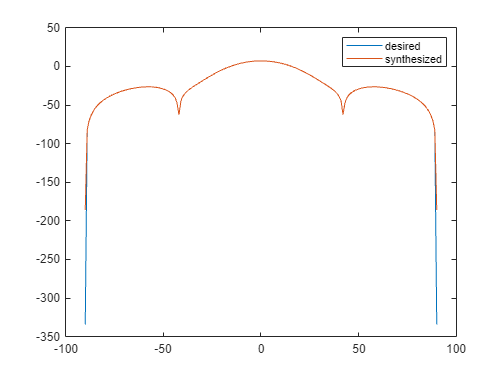


                                            % fmincon includes last 2 inputs 
                                            % which bound returned values to be
                                            % between zero and one

figure;
plot(az,mag2db([B_d;abs(w_o'*stvmat)]'))
legend("desired","synthesized")

## Optimize Both Weights and Element Position

Build Desired Pattern

N = 8;
az = -90:90;
w_d = hamming(N).*steervec((0:N-1)/2,10);
stvmat = steervec((0:N-1)/2,az);
B_d = abs(w_d'*stvmat);

Run Optimization

% break complex weights to real and imaginary
w_i_re = ones(N,1);                          % initial real values
w_i_im = zeros(N,1);                         % initial imaginary values 
x_i = (0:N-1)'/2;                            % initial locations

objfun = @(x)norm(abs((x(1:N)+1i*x(N+1:2*N))'*steervec(x(2*N+1:end).',az))-B_d);

x_ini = [w_i_re;w_i_im;x_i];

[x_o, fval, ef, output] = ...
    fmincon(objfun,x_ini,[],[],[],[],[-ones(2*N,1);(0:N-1)'/2-0.2],[ones(2*N,1);(0:N-1)'/2+0.2],...
    [], optimoptions(@fmincon,"Display","iter"));

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      25    1.597257e+01    0.000e+00    2.122e+00
    1      51    1.041490e+01    0.000e+00    8.611e+00    1.301e+00
    2      78    1.018229e+01    0.000e+00    6.702e+00    1.480e-01
    3     104    9.782837e+00    0.000e+00    6.280e+00    6.504e-01
    4     130    9.660277e+00    0.000e+00    1.484e+01    8.564e-01
    5     156    8.927152e+00    0.000e+00    9.100e+00    4.695e-01
    6     182    6.663083e+00    0.000e+00    1.495e+01    6.874e-01
    7     209    5.437520e+00    0.000e+00    1.945e+01    4.198e-01
    8     235    5.092395e+00    0.000e+00    1.201e+01    5.920e-01
    9     261    4.055893e+00    0.000e+00    6.108e+00    2.107e-01
   10     288    3.866453e+00    0.000e+00    1.731e+01    3.670e-01
   11     315

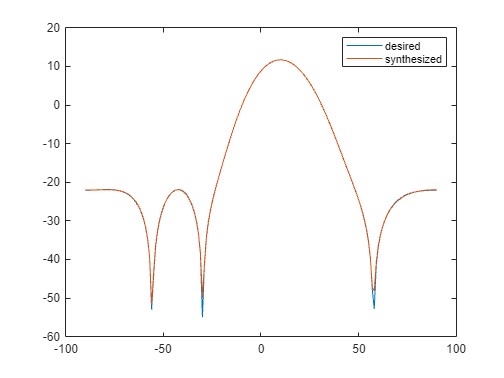


figure;
plot(az,mag2db([B_d;abs((x_o(1:N)+1i*x_o(N+1:2*N))'*steervec(x_o(2*N+1:end).',az))]'))
legend("desired","synthesized")

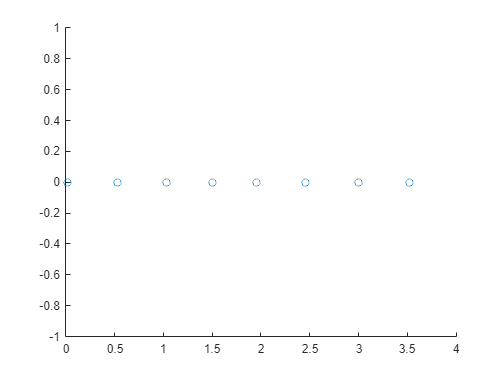

scatter(x_o(2*N+1:end), zeros(1,8))